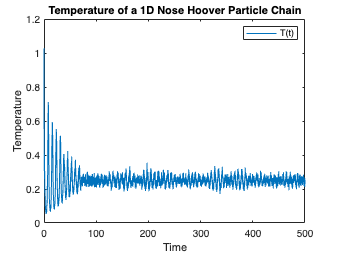

Target_Temperature = 0.25;
Q_Constant = 25;
Initial_Friction = 0.25;
Number_of_Particles = 100;
Time_Step = 0.025;
Number_of_Steps = 2e4;

[Time, Kinetic_Energy] = MD1D_Nose_Hoover(Time_Step, Number_of_Steps, Target_Temperature, Q_Constant, Initial_Friction, Number_of_Particles);

Temperature = 2*(Kinetic_Energy./Number_of_Particles);

plot(Time, Temperature);
title('Temperature of a 1D Nose Hoover Particle Chain');
xlabel('Time');
ylabel('Temperature');
legend('T(t)');

saveas(gcf, 'Q2b.png', 'png');

function [Time, Kinetic_Energy] = Nose_Hoover_Velocity_Verlet_Scheme(Initial_Positions, Initial_Velocities, Time_Step, Number_of_Steps, Target_Temperature, Q_Constant, Initial_Friction, Number_of_Particles)
 
    Positions = zeros(Number_of_Particles, Number_of_Steps);
    Velocities = zeros(Number_of_Particles, Number_of_Steps);
    Time = zeros(1, Number_of_Steps);
    Kinetic_Energy = zeros(1, Number_of_Steps);

    Positions(:, 1) = Initial_Positions;
    Velocities(:, 1) = Initial_Velocities;

    Initial_Force = forceLJ(Positions(:, 1));
    Kinetic_Energy(1) = KineticEnergy(Velocities(:,1));

    Friction = Initial_Friction;
    Current_Force= Initial_Force;

    for n = 1:Number_of_Steps

        Time(n+1) = Time(n) + Time_Step;

        Resistance_Vector = Current_Force - (Friction*Velocities(:,n));

        Positions(:, n+1) = Positions(:, n) + (Velocities(:, n)*Time_Step) + (Resistance_Vector*(Time_Step^2/2));
        New_Force = forceLJ(Positions(:, n+1));

        Friction = Friction + (Time_Step/Q_Constant)*(KineticEnergy(Velocities(:, n)) - (Number_of_Particles*Target_Temperature)/2) + (Time_Step^2/(2*Q_Constant))*dot(Velocities(:, n), Resistance_Vector);

        Velocities(:, n+1) = (Velocities(:, n) + (Time_Step/2)*(Resistance_Vector + New_Force))/(1 + (Time_Step/2)*Friction);
        Kinetic_Energy(n+1) = KineticEnergy(Velocities(:,n+1));

        Current_Force = New_Force;

    end
end









function [t, k]= MD1D_Nose_Hoover(dt, N, T0, Q, F0, M)
% 
% One-dimensional Molecular Dynamics Simulation
% ---------------------------------------------
%
% Input parameters:
% M - number of particles
% dt - time step
% N - number of time steps
%
% Output variables:
% t - the computational grid (an 1 x N vector) 
% x - the particle positions (an M x N matrix)
% v - the particle velocities (an M x N matrix)
% K - the kinetic energies (an 1 x N vector)
% U - the potential energies (an 1 X N vector) 

% Initial condition for the positions at t=0
x0=2^(1/6)*((0:M-1)+0.1*rand([1 M]))'; 
% Initial condition for the velocities at t=0
v0=randn([M 1]);
% Removing collective drift velocity
v0=v0-mean(v0); 

% Calling the Velocity Verlet algorithm

[t, k]=Nose_Hoover_Velocity_Verlet_Scheme(x0, v0, dt, N, T0, Q, F0, M);

end

function a=forceLJ(x)
%
% Calculating forces for the 1-dimensional Lennard-Jones system
% -------------------------------------------------------------
% 
% Input parameters:
% x - particle positions ( an M x 1 vector )
%
% Output variables

M=length(x);

for i=1:M
    xi=x(i)*ones(M,1);
    dx=xi-x;
    dx(i)=[];
    F=force(dx);
    a(i,1)=sum(F);
end

end

function f=force(dx)

C0=+1.9046328755214578*10^(-1);
C2=-6.3412495460455629*10^(-2);
C4=+8.4474726890347847*10^(-3);
C6=-5.2108756695106039*10^(-4); 
C8=+1.2399963699390198*10^(-5);

fLJ=4*(6*dx.^(-7)-12*dx.^(-13));

f=-(fLJ+8*C8*dx.^7+6*C6*dx.^5+4*C4*dx.^3+2*C2*dx);

f(abs(dx)>3)=0;

end

function U=PotentialEnergy(x)

[m, n]=size(x);

for i=1:n
    X=x(:,i);
    dx=X-X';
    u=potential(dx);
    u=u(u~=Inf);
    U(i,1)=sum(u)/2;
end

end

function u=potential(dx)

C0=+1.9046328755214578*10^(-1);
C2=-6.3412495460455629*10^(-2);
C4=+8.4474726890347847*10^(-3);
C6=-5.2108756695106039*10^(-4); 
C8=+1.2399963699390198*10^(-5);

uLJ=4*(dx.^(-12)-dx.^(-6));

u=uLJ+C8*dx.^8+C6*dx.^6+C4*dx.^4+C2*dx.^2+C0;

u(abs(dx)>3)=0;

u=uLJ;

end

function K=KineticEnergy(v)

[m, n]=size(v);

for i=1:n
    V=v(:,i);
    K(i,1)=(1/2)*dot(V,V);
end

end
